# **フーリエ級数の収束と発散**

## 1. フーリエ級数の定義

本稿を通じて実数直線 $\mathbb{R}$ 上の周期 $1$ の区分的連続周期関数を考える. すなわち次をみたす関数 $f(x)$ を考える:

$f(x+1)=f(x)$ がすべての $x\in\mathbb{R}$ で成立する.

有限個の実数 $0=a_0<a_1<\cdots<a_m=1$ が存在して $f(x)$ は各開区間 $(a_{j-1},a_j)$, $j=1,\ldots,m$, で連続であり, その他の点では有限な片側極限値 


$$f(a_0+0), 
\quad
f(a_1-0),
\quad
f(a_1+0),
\quad
\ldots
\quad
f(a_m-0)$$


が存在する. 

このような関数 $f(x)$ を各閉区間 $[a_{j-1}+k,a_j+k]$ for $j=1,\ldots,m$ and $k\in\mathbb{Z}$, に制限すると, $f(x)$ は連続関数とみなすことができることに注意する. 実数直線上の $1$-周期区分的連続関数の全体を $\mathcal{L}$ と表すことにする. 

すべての $e^{2\pi i n x}=\cos(2\pi nx)+i\sin(2\pi nx)$, $n \in \mathbb{Z}$ なる関数は周期 $1$ の$C^\infty$級周期関数である. フーリエ (Joseph Fourier, 1768-1830) の着想に習って, **関数 **$f(x) \in \mathcal{L}$** は次の形の三角関数の級数で表されるか否かを考えよう**. 


$$\sum_{n=-\infty}^\infty
c_ne^{-2\pi i n x}.$$


もし $f(x)
=
\sum_{n=-\infty}^\infty
c_ne^{-2\pi i n x}$ が成立するならば, 形式的な計算では 


$$\int_0^1
f(x)e^{-2\pi i mx}
dx
=
\int_0^1
\sum_{n=-\infty}^{\infty}
c_n
e^{2\pi i(n-m)x}
dx
=
\sum_{n=-\infty}^\infty
c_n
\int_0^1
e^{2\pi i (n-m)x}
dx
=
\sum_{n=-\infty}^\infty
c_n\delta_{mn}
=
c_m.$$


が成立する. $f(x) \in \mathcal{L}$ により左辺のリーマン積分の存在は保証される. 次の形式的な三角関数の級数


$$\sum_{n=-\infty}^\infty
c_ne^{-2\pi i n x}, 
\quad
c_n
=
\int_0^1
f(x)e^{-2\pi i nx}
dx$$


を $f(x)$ のフーリエ級数とよび, このことを以下の記号で略記する.  


$$f(x)
\sim
\sum_{n=-\infty}^\infty
c_n
e^{2\pi i nx}.$$


また $c_n$ は $f(x)$ の$n$番目のフーリエ係数という.

## 2. 実数値関数のフーリエ級数の実数値形式

関数 $f(x)$ が実数値関数であるとき, そのフーリエ級数を実数値関数 


$$1=\cos(2\pi 0 x),
\quad
\cos(2\pi n x),
\quad
\sin(2\pi nx),
\quad
n=1,2,3,\ldots$$


の実数値係数の級数として表してみよう.  このとき $\overline{c_{-n}}=c_n$ が成立し $c_0$ は実数値になる. そこで, $n=0,1,2,\ldots$ に対して


$$\overline{c_n}=c_{-n}
=
\frac{a_n+ib_n}{2}, 
\quad
a_n
=
2
\int_0^1
f(x)
\cos(2\pi nx)
dx,
\quad
b_n
=
2
\int_0^1
f(x)
\sin(2\pi nx)
dx,$$


とおくことにすると, $b_0=0$ であり, 次が成立することがわかる. 


$$f(x)
\sim
\frac{a_0}{2}
+
\sum_{n=1}^\infty
\bigl(
a_n\cos(2\pi nx)
+
b_n\sin(2\pi nx)
\bigr).$$


よって, 実数値関数のフーリエ級数を求めるには以下を計算するのが便利であろう. 


$$\frac{a_0}{2}
=
C_0
=
\int_0^1f(x)dx,$$



$$a_n+ib_n
=
2C_{-n}
=
2
\int_0^1
f(x)e^{2\pi i nx}
dx, 
\quad
n=1,2,3,\ldots.$$


なお $\lambda=\mu+i\nu \in \mathbb{C}, 
\quad
\mu,\nu \in \mathbb{R}$ に対して


$$e^{\lambda x}
=
e^{\mu x + i\nu x}
=
e^{\mu x}
\{\cos(\nu x)+i\sin(\nu x)\},$$



$$\frac{d}{dx}e^{\lambda x}
=
\frac{d}{dx}
\bigl[
e^{\mu x}
\{\cos(\nu x) + i\sin(\nu x)\}
\bigr]$$



$$\qquad
=
\mu e^{\mu x}
\{\cos(\nu x) + i\sin(\nu x)\}
+
\nu
e^{\mu x}
\{-\sin(\nu x) + i\cos(\nu x)\}$$



$$\qquad
=
\mu e^{\mu x}
\{\cos(\nu x) + i\sin(\nu x)\}
+
i\nu
e^{\mu x}
\{i\sin(\nu x) + \cos(\nu x)\}$$



$$\qquad
=
(\mu + i\nu)
e^{\mu x}
\{\cos(\nu x) + i\sin(\nu x)\}
=
\lambda e^{\lambda x}$$


が成り立つ. これはフーリエ係数の計算に有用である.

## 3. フーリエ級数の例

 周期 $1$ の実数値関数$f(x)$ を次のように定義する. 


$$f(x) 
:= 
\min\{x-[x],1-x-[1-x]\},
\quad
x\in\mathbb{R},$$



$$[s]:=\max\{m \in \mathbb{Z} :  m \leq s\}, 
\quad
s\in\mathbb{R}.$$


関数 $f(x)$ は閉区間 $[0,1]$ 上では 


$$f(x)
=
\cases{x, &\quad x\in[0,1/2), \cr 1-x, &\quad x\in[1/2,1),}$$
 

となり, 三角形関数 (の周期化関数) とよばれる. この関数のフーリエ級数は  


$$f(x)
\sim
\frac{1}{4}
-
\sum_{k=1}^\infty
\frac{2}{(2k-1)^2\pi^2}
\cos\bigl(2(2k-1)\pi x\bigr).$$


で与えられることを確認してみよう. 実際


$$\frac{a_0}{2}
=
\int_0^{1/2}xdx
+
\int_{1/2}^1(1-x)dx
=
\frac{2}{2^3}
=
\frac{1}{4},$$



$$a_n+ib_n
=
2\int_0^{1/2}
xe^{2\pi i nx}
dx
+
2\int_{1/2}^1
(1-x)e^{2\pi i nx}
dx$$



$$\qquad
=
\left[
\frac{xe^{2\pi i nx}}{n\pi i}
\right]_0^{1/2}
+
\left[
\frac{(1-x)e^{2\pi i nx}}{n\pi i}
\right]_{1/2}^1
-
\int_0^{1/2}
\frac{e^{2\pi i nx}}{n\pi i}
dx
+
\int_{1/2}^1
\frac{e^{2\pi i nx}}{n\pi i}
dx$$



$$\qquad
=
0
-
\left[
\frac{e^{2\pi i nx}}{2(n\pi i)^2}
\right]_0^{1/2}
+
\left[
\frac{e^{2\pi i nx}}{2(n\pi i)^2}
\right]_{1/2}^1
$$



$$\qquad
=
\frac{e^{\pi i n}-1-1+e^{\pi i n}}{2n^2\pi^2}
=
\frac{\cos(n\pi)-1}{n^2\pi^2}
=
-
\frac{1-(-1)^n}{n^2\pi^2}$$



$$\qquad
=
\cases{-\frac{2}{(2k-1)^2\pi^2}, &\quad n=2k-1, \cr 0, &\quad n=2k,}
\quad
k=1,2,3,\ldots$$


となって確かめられる. 

## 4. ディリクレ核

改めて $f(x) \in \mathcal{L}$ かつ $f(x)
\sim
\sum_{n=-\infty}^\infty
c_ne^{-2\pi i n x}$ とする. 本稿の主たる問いは次のように述べられる. 

- **Q1. **$f(x)$** のフーリエ級数 **$\sum_{n=-\infty}^\infty
c_ne^{-2\pi i n x}$** は収束して関数になるのか ?**

- **Q2. **$\sum_{n=-\infty}^\infty
c_ne^{-2\pi i n x}$** が収束して関数になるとき, それは **$f(x)$** に一致するのか?**

ここで $f(x)$ のフーリエ級数の$N$番目の部分和を


$$S_N(x)
:=
\sum_{n=-N}^N
c_ne^{2\pi i nx}. $$


と表すことにする. フーリエ係数の定義を利用すると


$$S_N(x)
=
\int_0^1
D_N(x-y)
f(y)
dy
=
\int_{-1/2}^{1/2}
D_N(t)
f(x+t)
dt,$$



$$D_N(t)
=
\sum_{n=-N}^N
e^{2\pi i nt}
=
1
+
2
\sum_{n=1}^N
\cos(2\pi nx).$$


となる. $D_N(t)$ は$N$番目のディリクレ核 (N-th Dirichelet kernel) とよばれる. $D_N(t)$ は周期 $1$ の$C^\infty$級周期関数であり


$$\int_0^1D(t)dt=1.$$


をみたす. さらに有限等比数列の和とみなすと 


$$D_N(t)
=
\cases{\frac{\sin\bigl(\pi(2N+1)t\bigr)}{\sin(\pi t)}, &\quad t\not\in\mathbb{Z}, \cr 2N+1, &\quad t\in\mathbb{Z}.}$$
 

が得られるが, これは $D_N(t)$ の挙動を端的によく表しており, フーリエ級数の収束を論ずるのに有用である. 

周期1つ分の閉区間 $[-1/2,1/2]$ において$D_N(t)$ を観察してみよう. 粗く言って, $N$が大きくなるときの $D_N(t)$ の挙動は次のようになる. 

- 質量 (周期1つ分の積分値) が区間 $I_N:=[-1/(2N+1),1/(2N+1)]$ に集中する**.**

- $I_N$ の外である $[-1,-1/(2N+1))\cup(1/(2N+1),1]$ では振動がどんどん激しくなる. 

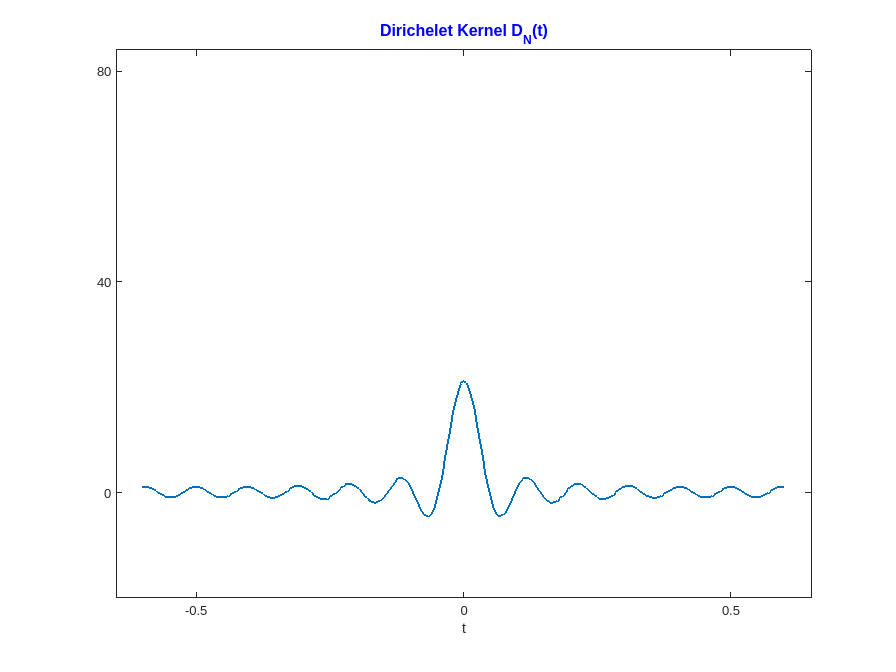

M=40;
N =10;

t = -0.6:0.005:0.6;
S=ones(M+1,241);
for m=2:M+1
    for k=1:241
        S(m,k)=S(m-1,k)+2*cos(2*pi*(m-1)*t(1,k));
    end
end

plot(t,S(N+1,:),'LineWidth',1.5);
   ylim([-M/2 2*M+M/10])
   xlim([-0.65 0.65])
   title('Dirichelet Kernel D_N(t)','Color','blue','FontSize',12)
   xlabel('t')
   xticks([-0.5 0 0.5])
   yticks([0 M 2*M])

## 5. 連続な周期関数のフーリエ級数の収束と発散 

 連続な周期関数のフーリエ級数の収束と発散については次がよく知られている. 

**1. **$\alpha \in (0,1]$** とする. 関数 **$f(x)$** は**$\alpha$**-次ヘルダー連続な周期 **$1$** の周期関数とする. すなわち, **$f(x)$** は周期 **$1$** の周期関数であり, ある **$L>0$** が存在して **$|f(x)-f(y)| \leq L|x-y|^\alpha$** がすべての **$x,y\in\mathbb{R}$** に対して成立するものとする. このとき, **$f(x)$** のフーリエ級数は **$f(x)$** に一様収束する:**


$$\max_{x\in[0,1]}
\left|S_N(x)-f(x)\right|
\rightarrow
0
\quad
(N \rightarrow \infty).$$


**2. 特に **$\alpha>1/2$** であるとき**


$$\sum_{n=-\infty}^{\infty}
|c_n|
<\infty$$


**が成立するので, **$f(x)$** のフーリエ級数は一様に絶対収束する. **

**3. 周期 **$1$** の連続な周期関数 **$f(x)$** が存在して, **


$$S_N(0) \rightarrow \infty
\quad
(N \rightarrow \infty)$$


**が成立する. すなわち, フーリエ級数が各点収束しない周期 **$1$** の連続な周期関数が存在する. **

ヘルダー (Hoelder) 連続性について少し補足する. まず連続な周期関数は最大絶対値をもつので, 条件式 $|f(x)-f(y)| \leq L|x-y|^\alpha$ は小さい $|x-y|$ に対してのみ有効である. 粗く言うと, 指数 $\alpha$ は $f(x)$ が各点で$\alpha$回微分可能であることを表している. $\alpha=1$のヘルダー連続性はリプシッツ (Lipshitz) 連続性とよばれる. ラデマッハ (Rademach) の定理によると,  1変数リプシッツ連続関数は $\mathbb{R}$ 上のルベーグ (Lebesgue) 測度に関してほとんどいらるところ微分可能である. **パート1**と**パート3**は、周期関数 $f(x)$ が連続関数よりもほんの少し滑らかであればそのフーリエ級数は $f(x)$ に一様収束するが, そうでなければ (単なる連続関数というだけでは) フーリエ級数が必ずしも各点収束すらしないことを主張している.  

**パート 1 **の証明の概略を述べよう. まず $S_N(x)-f(x)$ は次のようにも表されること注意する. 


$$S_N(x)-f(x)
=
\int_{-1/2}^{1/2}
D_N(t)
\{f(x+t)-f(x)\}
dt.$$


ヘルダー条件を利用すると, 十分小さい任意の $\delta>0$ に対して次が得られる. 


$$S_N(x)-f(x)
=
\int_{|t|<\delta}
O(|t|^{-1+\alpha})
dt
+
\int_{\delta<|t|<1/2}
\sin\bigl(\pi(2N+1)t\bigr)
\times
\cdots
dt.$$


右辺の第2項は $N \rightarrow \infty$ のとき振動がどんどん激しくなることと $\int_0^1\sin(2\pi x)dx=0$ により $0$ に収束する. 実際, 任意の $\varphi(t) \in C^1[0,1]$ に対して次が成立する.  


$$\int_0^1\sin(2\pi Nt)\varphi(t)dt
=
\left[-\frac{\cos(2\pi Nt) \varphi(t)}{2\pi N}\right]_0^1
+
\int_0^1
\frac{\cos(2\pi Nt) \varphi^\prime(t)}{2\pi N}
dt
=
O(N^{-1})
\quad
(N \rightarrow \infty).$$


テスト関数 $\varphi(t)$ の微分可能性は実際には不要であり,  任意の $\varphi(t) \in C[0,1]$ に対して $\varphi(t)$ の一様連続性と $\int_0^1\sin(2\pi x)dx=0$ を用いると


$$\int_0^1\sin(2\pi Nt)\varphi(t)dt
\rightarrow 0
\quad
(N \rightarrow \infty)$$


を示すことができる. よって任意の $\delta>0$ に対して


$$S_N(x)-f(x)
=
O(\delta^\alpha)
+
o(1)
\quad
(N \rightarrow 0)$$


が得られる. 

## 6. 三角形関数のフーリエ級数の一様収束

周期 $1$ の三角形関数 


$$f(x)
=
\cases{x, &\quad x\in[0,1/2), \cr 1-x, &\quad x\in[1/2,1).}$$


はリプシッツ連続であり, そのフーリエ級数 


$$f(x)
=
\frac{1}{4}
-
\sum_{k=1}^\infty
\frac{2}{(2k-1)^2\pi^2}
\cos\bigl(2(2k-1)\pi x\bigr),$$


は $f(x)$ に一様収束する. そのことを観察してみよう. 部分和を次のようにおく. 


$$S^\prime_K[f](x)
=
\frac{1}{4}
-
\sum_{k=1}^K
\frac{2}{(2k-1)^2\pi^2}
\cos\bigl(2(2k-1)\pi x\bigr).$$


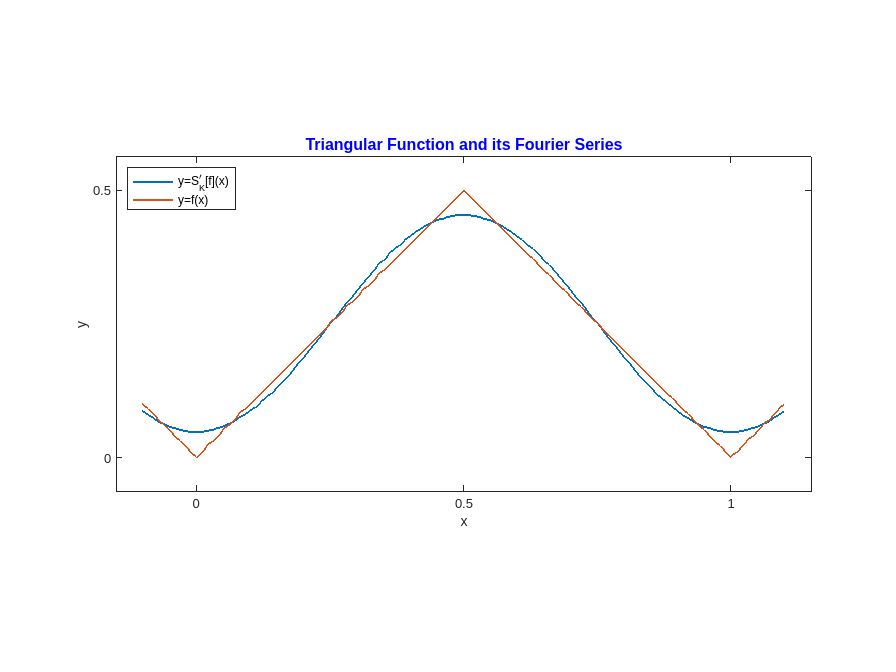

x = -0.1 : 0.01 : 1.1;
f = min(x-floor(x),1-x-floor(1-x));

M1=20;

K =1;
S1=ones(M1+1,121)/4;
for k=2:M1+1
    for l=1:121
        S1(k,l)=S1(k-1,l)-2*cos(2*(2*k-3)*pi*x(1,l))/(2*k-3)^2/pi^2;
    end
end

plot(x,S1(K+1,:),x,f,'LineWidth',1.5)
axis equal
ylim([-1/16 9/16])
xlim([-0.15 1.15])
title('Triangular Function and its Fourier Series','Color','blue','FontSize',12)
xlabel('x')
xticks([0 1/2 1])
yticks([0 1/2])
ylabel('y')
legend('y=S^\prime_K[f](x)','y=f(x)','Location','northwest')

## 7. 階段関数とのこぎり歯関数のフーリエ級数

関数 $Y(x)$ はヘビサイド (Heaviside) 関数とする.


$$Y(x)
=
\cases{1, &\quad x\geq0, \cr 0, &\quad x<0.}$$


点 $x=0$ での値 $Y(0)$ は本質的ではなく, 実際には定義する必要はない.  周期 $1$ の周期化された階段関数 $g(x)$ とのこぎり歯関数 $h(x)$ を


$$g(x)
:=
\sum_{k=-\infty}^\infty
Y(x+k){\times}Y(1/2-x-k),
\quad
h(x):=x-[x]$$


と定義する. 変数を $x\in[0,1)$ に制限すると次のようになる.


$$g(x)
=
\cases{1, &\quad x\in[1,1/2], \cr 0, &\quad x\in (1/2,1),}
\qquad
h(x)=x.
$$


$g(x)$ は不連続点 $k, k+1/2, k\in\mathbb{Z}$ をもち, $h(x)$ は不連続点 $k \in \mathbb{Z}$ をもつ. これらはのフーリエ級数は以下のようになり, それぞれ部分和の記号を設定する.


$$g(x)
\sim
\frac{1}{2}
+
\sum_{k=1}^\infty
\frac{2}{(2k-1)\pi}
\sin\bigl(2(2k-1)\pi x\bigr),$$



$$S^\prime_K[g](x)
=
\frac{1}{2}
+
\sum_{k=1}^K
\frac{2}{(2k-1)\pi}
\sin\bigl(2(2k-1)\pi x\bigr),$$



$$h(x)
\sim
\frac{1}{2}
-
\sum_{n=1}^\infty
\frac{1}{n\pi}
\sin(2n\pi x),$$



$$S_N[h](x)
=
\frac{1}{2}
-
\sum_{n=1}^N
\frac{1}{n\pi}
\sin(2n\pi x).$$


それぞれ不連続点では次が成立することに注意する. 


$$S^\prime_K[g](k)
=
\frac{1}{2}
\rightarrow
\frac{1}{2}
=
\frac{g(k-0)+g(k+0)}{2}
\quad
(K \rightarrow \infty),$$



$$S^\prime_K[g](k+1/2)
=
\frac{1}{2}
\rightarrow
\frac{1}{2}
=
\frac{g(k+1/2-0)+g(k+1/2+0)}{2}
\quad
(K \rightarrow \infty),$$



$$S_N[h](k)
=
\frac{1}{2}
\rightarrow
\frac{1}{2}
=
\frac{h(k-0)+h(k+0)}{2}
\quad
(N \rightarrow \infty),$$


ここに $k \in \mathbb{Z}$ である. 一方, 不連続点の近傍以外では, フーリエ級数がもとの関数に一様収束することが知られている. 具体的には, 十分小さい $\delta>0$ に対して次が成立する. 


$$\max_{x\in[\delta,1/2-\delta]\cup[1/2+\delta,1-\delta]}
|S^\prime_K[g](x)-g(x)|
\rightarrow 0
\quad
(K \rightarrow \infty),$$



$$\max_{x\in[\delta,1-\delta]}
|S_N[h](x)-h(x)|
\rightarrow 0
\quad
(N \rightarrow \infty).$$


部分和の項数 $N$ が増えるにつれて部分和は不連続点付近で激しく振動する.  これは**ギブス現象** (**Gibbs Phenomenon**) とよばれる. これを観察してみよう. 

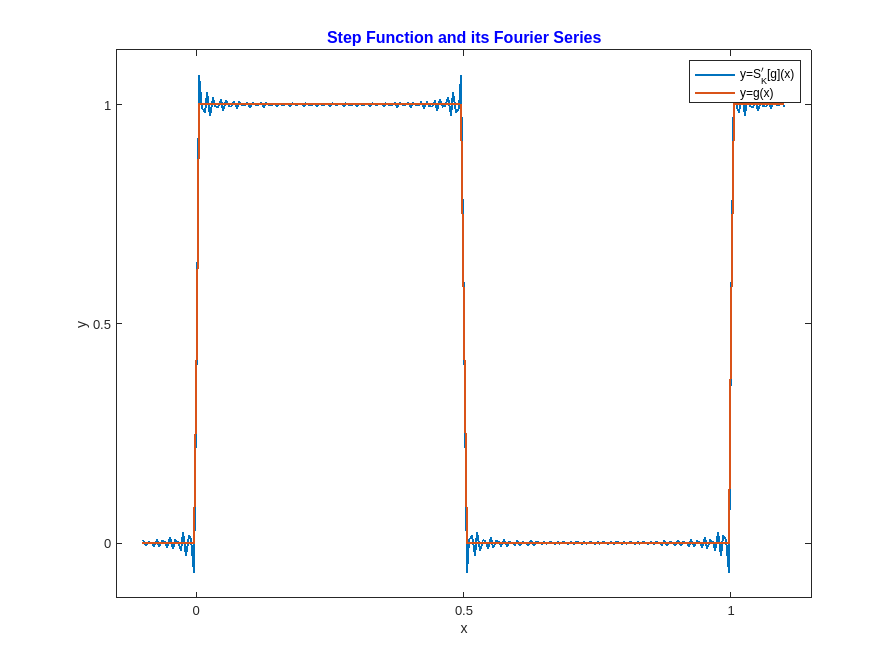

x1 = -0.1 : 0.005 : 1.1;
g = heaviside(x1+1).*heaviside(1/2-x1-1)+heaviside(x1).*heaviside(1/2-x1)+heaviside(x1-1).*heaviside(1/2-x1+1);
M2=40;
K =40;
S2=ones(M2+1,241)/2;
for k=2:M2+1
    for l=1:241
        S2(k,l)=S2(k-1,l)+2*sin(2*(2*k-3)*pi*x1(1,l))/(2*k-3)/pi;
    end
end

plot(x1,S2(K+1,:),x1,g,'LineWidth',1.5)
%axis equal
ylim([-1/8 9/8])
xlim([-0.15 1.15])
title('Step Function and its Fourier Series','Color','blue','FontSize',12)
xlabel('x')
xticks([0 1/2 1])
yticks([0 1/2 1])
ylabel('y')
legend('y=S^\prime_K[g](x)','y=g(x)','Location','northeast')

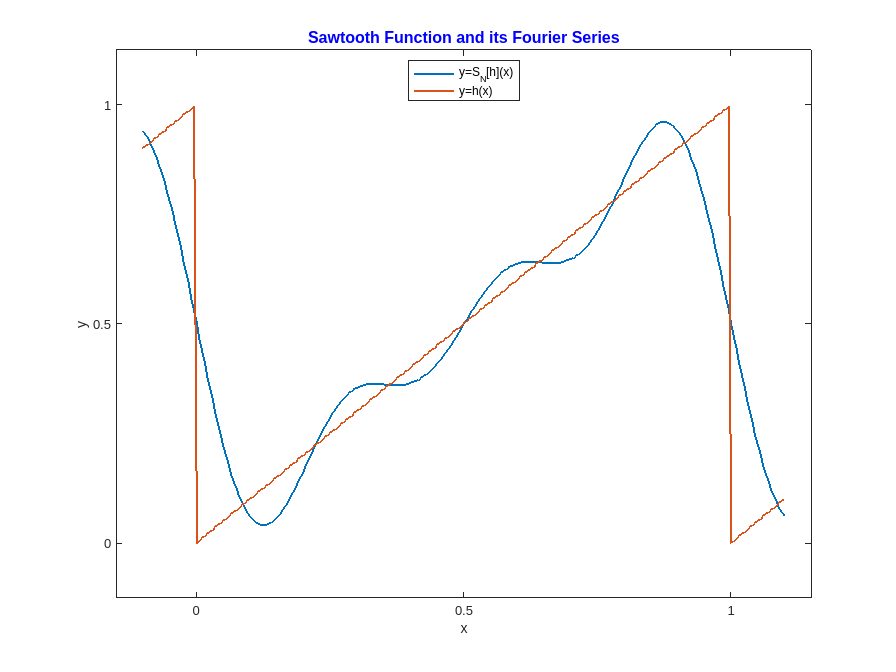

x2 = -0.1 : 0.005 : 1.1;
h = x2-floor(x2);
M3=50;
N =3;
S3=ones(M3+1,241)/2;
for n=2:M3+1
    for l=1:241
        S3(n,l)=S3(n-1,l)-sin(2*(n-1)*pi*x2(1,l))/(n-1)/pi;
    end
end

plot(x2,S3(N+1,:),x2,h,'LineWidth',1.5)
%axis equal
ylim([-1/8 9/8])
xlim([-0.15 1.15])
title('Sawtooth Function and its Fourier Series','Color','blue','FontSize',12)
xlabel('x')
xticks([0 1/2 1])
yticks([0 1/2 1])
ylabel('y')
legend('y=S_N[h](x)','y=h(x)','Location','north')

## 8. 区分的に$C^1$級の周期関数の分解

区分的に$C^1$級の周期$1$ の周期関数はリプシッツ連続な関数, および, のこぎり歯と有限個の階段関数の1次結合に分解できることを示そう. 1変数関数 $f(x)$ が区分的に$C^1$級の周期$1$ の周期関数であるとは, 次をみたすことである.

$f(x+1)=f(x)$ for all $x\in\mathbb{R}$.

有限個の数 $0=a_0<a_1<\cdots<a_m=1$ が存在して $f(x)$ は各開区間 $(a_{j-1},a_j)$, $j=1,\ldots,m$,  で$C^1$級であり, 

それ以外の有限個の点では有限な片側極限値 


$$f(a_0+0), 
\quad
f(a_1-0),
\quad
f(a_1+0),
\quad
\ldots
\quad
f(a_m-0),$$



$$f^\prime(a_0+0), 
\quad
f^\prime(a_1-0),
\quad
f^\prime(a_1+0),
\quad
\ldots
\quad
f^\prime(a_m-0)$$


が存在する. 

区分的に$C^1$級の周期関数 $f(x)$ を各閉区間 $[a_{j-1}+k,a_j+k]$, $j=1,\ldots,m$, $k\in\mathbb{Z}$, に制限すると, $f(x)$ は$C^1$級関数とみなせることに注意する. 以下の簡単な例を使って $f(x)$ の分解を説明する. 

関数 $f(x)$ は区分的に$C^1$級で周期 $1$ 周期関数であるとし,  $C^1$級であることが成り立たない特異点は閉区間 $[0,1]$ において $0,c,1$ の3点とする. ここに $c\in(0,1)$ とする. 周期性により $f(0\pm0)=f(1\pm0)$ であることに注意する. 区間  $[c,1]$ の特性関数を $\chi_{[c,1]}(x)$ とする. $f_0(x)$, $f_1(x)$, $f_2(x)$ を以下のように定義する. 


$$f_0(x)
=
f(x)-f_1(x)-f_2(x),$$



$$f_1(x)
:=
\bigl(f(c+0)-f(c-0)\bigr)
\chi_{[c,1]}(x),$$



$$f_2(x)
=
-
\bigl\{
\bigl(f(0+0)-f(0-0)\bigr)
+
\bigl(f(c+0)-f(c-0)\bigr)
\bigr\}
h(x).$$


このとき $f_0(x)$ はリプシッツ連続になる. よって $f(x)$ はリプシッツ連続な $f_0(x)$ と不連続性を継承した具体的で単純な形の関数 $f_1(x)+f_2(x)$ に分解される. $f(x)$ のフーリエ級数では $f_0(x)$ のフーリエ級数は一様収束するが,  $f_1(x)+f_2(x)$ のフーリエ級数は不連続点でギブス現象を起こす. この分解を下記の例で観察してみよう. 

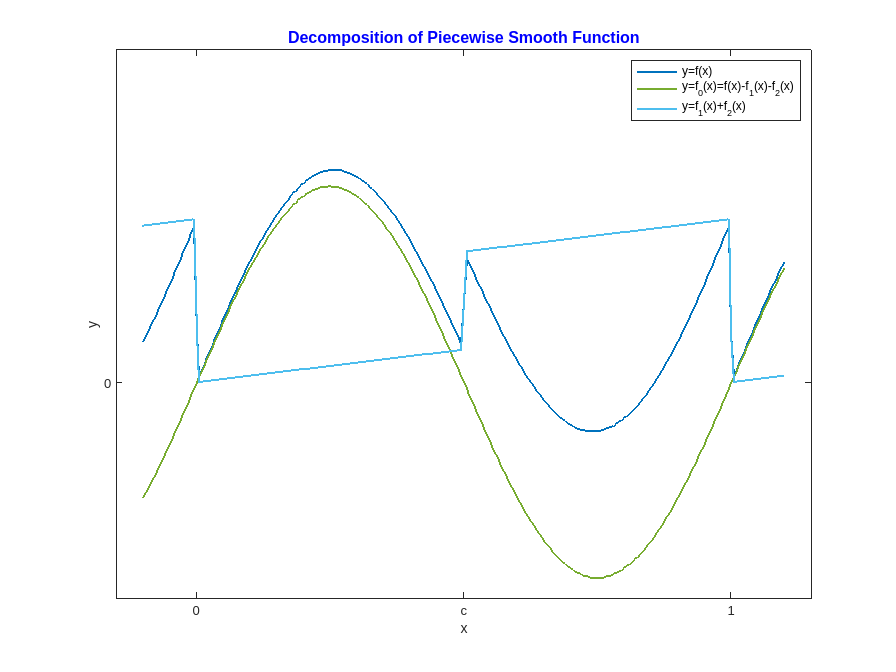

x3 = -0.1 : 0.005 : 1.1;
chi=heaviside(x3-1/2).*heaviside(1-x3)+heaviside(x3+1-1/2).*heaviside(-x3)+heaviside(x3-3/2).*heaviside(2-x3);
lin=x3-floor(x3);
F=sin(2*pi*x3)+chi/2+lin/3;
F1=chi/2;
F2=lin/3;
F0=F-F1-F2;
Z=100*ones(1,241);

plot(x3,F,x3,Z,x3,Z,x3,Z,x3,F0,x3,F1+F2,'LineWidth',1.5)
ylim([-1.1 1.7])
xlim([-0.15 1.15])
title('Decomposition of Piecewise Smooth Function','Color','blue','FontSize',12)
xlabel('x')
xticks([0 1/2 1])
xticklabels({'0','c','1'})
yticks([0])
ylabel('y')
legend('y=f(x)','','','','y=f_0(x)=f(x)-f_1(x)-f_2(x)','y=f_1(x)+f_2(x)','Location','northeast')

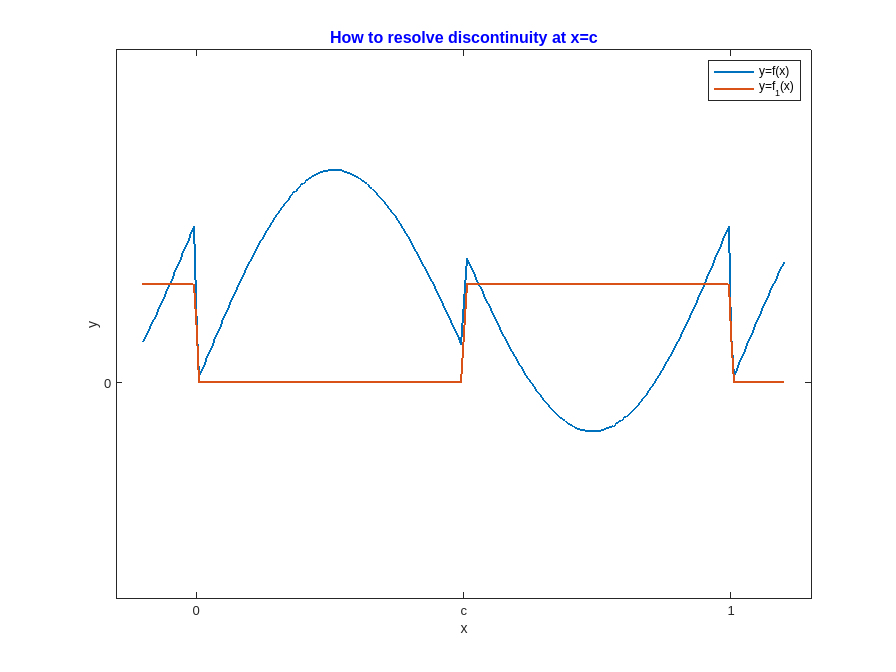

plot(x3,F,x3,F1,'LineWidth',1.5)
ylim([-1.1 1.7])
xlim([-0.15 1.15])
title('How to resolve discontinuity at x=c','Color','blue','FontSize',12)
xlabel('x')
xticks([0 1/2 1])
xticklabels({'0','c','1'})
yticks([0])
ylabel('y')
legend('y=f(x)','y=f_1(x)','Location','northeast')

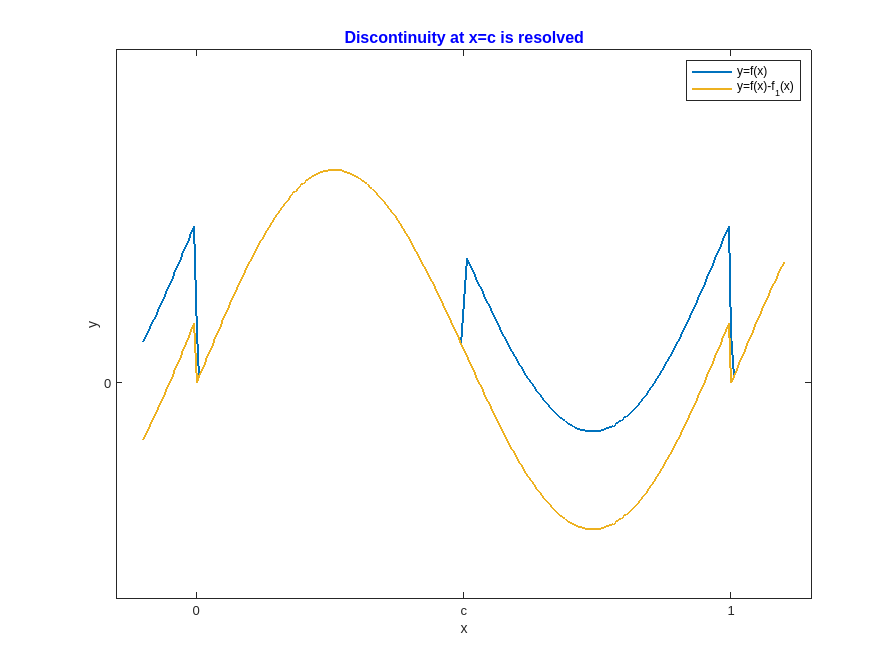

plot(x3,F,x3,Z,x3,F-F1,'LineWidth',1.5)
ylim([-1.1 1.7])
xlim([-0.15 1.15])
title('Discontinuity at x=c is resolved','Color','blue','FontSize',12)
xlabel('x')
xticks([0 1/2 1])
xticklabels({'0','c','1'})
yticks([0])
ylabel('y')
legend('y=f(x)','','y=f(x)-f_1(x)','Location','northeast')

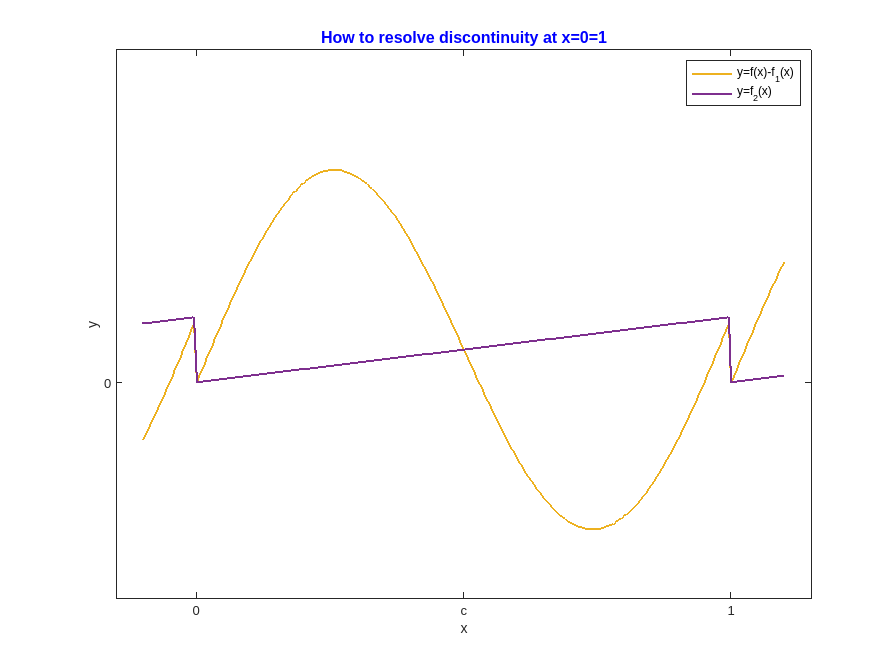

plot(x3,Z,x3,Z,x3,F-F1,x3,F2,'LineWidth',1.5)
ylim([-1.1 1.7])
xlim([-0.15 1.15])
title('How to resolve discontinuity at x=0=1','Color','blue','FontSize',12)
xlabel('x')
xticks([0 1/2 1])
xticklabels({'0','c','1'})
yticks([0])
ylabel('y')
legend('','','y=f(x)-f_1(x)','y=f_2(x)','Location','northeast')

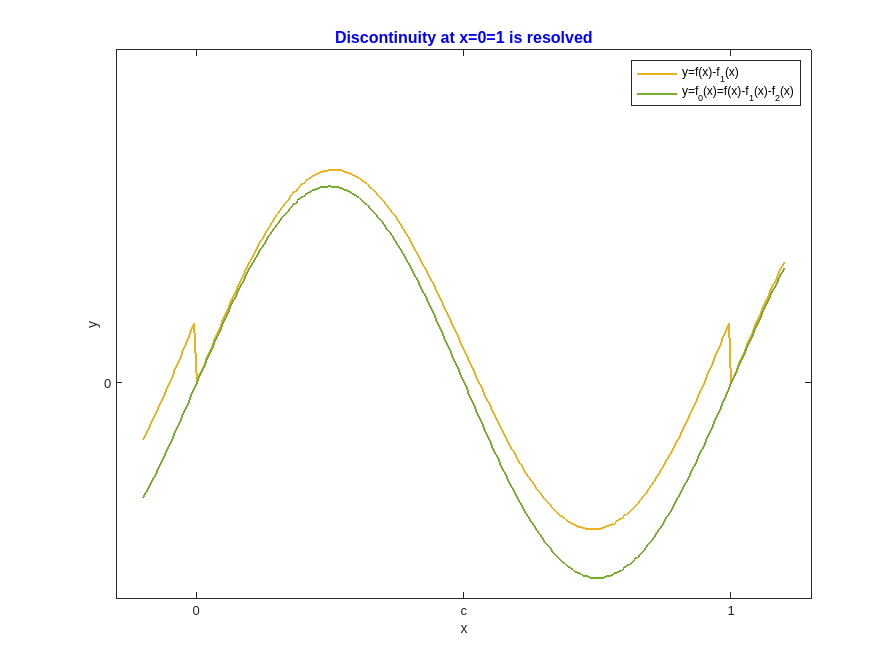

plot(x3,Z,x3,Z,x3,F-F1,x3,Z,x3,F0,'LineWidth',1.5)
ylim([-1.1 1.7])
xlim([-0.15 1.15])
title('Discontinuity at x=0=1 is resolved','Color','blue','FontSize',12)
xlabel('x')
xticks([0 1/2 1])
xticklabels({'0','c','1'})
yticks([0])
ylabel('y')
legend('','','y=f(x)-f_1(x)','','y=f_0(x)=f(x)-f_1(x)-f_2(x)','Location','northeast')